x1=linspace(8.5,11.5,31)

x1 =     8.5000    8.6000    8.7000    8.8000    8.9000    9.0000    9.1000    9.2000    9.3000    9.4000    9.5000    9.6000    9.7000    9.8000    9.9000   10.0000   10.1000   10.2000   10.3000   10.4000   10.5000   10.6000   10.7000   10.8000   10.9000   11.0000   11.1000   11.2000   11.3000   11.4000   11.5000


y1=[-2.6 -2.53 -2.34 -2.16 -1.986 -1.813 -1.643 -1.464 -1.289 -1.107 -0.939 -0.775 -0.594 -0.412 -0.029 -0.030 0.134 0.303 0.497 0.684 0.861 1.037 1.225 1.429 1.620 1.809 1.990 2.19 2.40 2.60 2.80]

y1 =    -2.6000   -2.5300   -2.3400   -2.1600   -1.9860   -1.8130   -1.6430   -1.4640   -1.2890   -1.1070   -0.9390   -0.7750   -0.5940   -0.4120   -0.0290   -0.0300    0.1340    0.3030    0.4970    0.6840    0.8610    1.0370    1.2250    1.4290    1.6200    1.8090    1.9900    2.1900    2.4000    2.6000    2.8000


plot(x1,y1,'+')
hold on
k1=polyfit(x1,y1,1)

k1 =     1.8116  -18.1200


x=linspace(8,12)

x =     8.0000    8.0404    8.0808    8.1212    8.1616    8.2020    8.2424    8.2828    8.3232    8.3636    8.4040    8.4444    8.4848    8.5253    8.5657    8.6061    8.6465    8.6869    8.7273    8.7677    8.8081    8.8485    8.8889    8.9293    8.9697    9.0101    9.0505    9.0909    9.1313    9.1717    9.2121    9.2525    9.2929    9.3333    9.3737    9.4141    9.4545    9.4949    9.5354    9.5758    9.6162    9.6566    9.6970    9.7374    9.7778    9.8182    9.8586    9.8990    9.9394    9.9798


y=k1(1)*x+k1(2)

y =    -3.6274   -3.5542   -3.4810   -3.4078   -3.3346   -3.2614   -3.1882   -3.1150   -3.0419   -2.9687   -2.8955   -2.8223   -2.7491   -2.6759   -2.6027   -2.5295   -2.4563   -2.3831   -2.3099   -2.2367   -2.1635   -2.0903   -2.0171   -1.9439   -1.8707   -1.7975   -1.7243   -1.6511   -1.5780   -1.5048   -1.4316   -1.3584   -1.2852   -1.2120   -1.1388   -1.0656   -0.9924   -0.9192   -0.8460   -0.7728   -0.6996   -0.6264   -0.5532   -0.4800   -0.4068   -0.3336   -0.2604   -0.1872   -0.1141   -0.0409


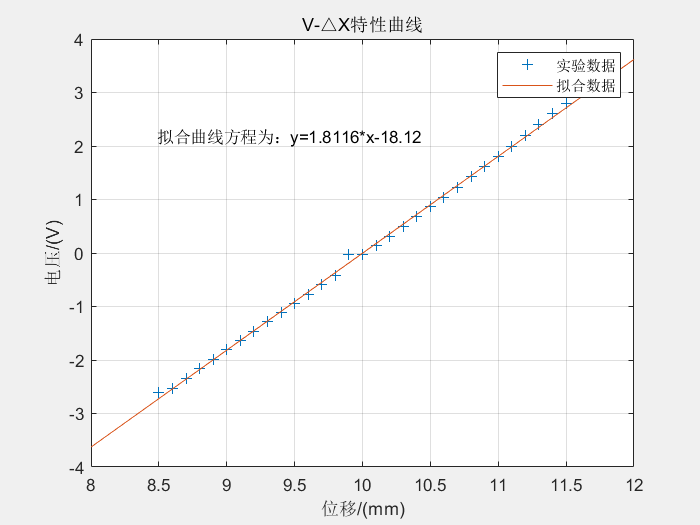

plot(x,y)

grid on
legend('实验数据','拟合数据')
xlabel('位移/(mm)')
ylabel('电压/(V)')

xlim([8.00 12.00])
ylim([-4.00 4.00])
title('V-△X特性曲线')
gtext('拟合曲线方程为：y=1.8116*x-18.12')


[maxy,num]=max(abs(k1(1)*x1+k1(2)-y1))

maxy = 0.1564

num = 15

%求最大非线性偏差(绝对值)，num为误差最大处向量位置
fxxwc=abs(maxy/max(y1))%计算非线性误差

fxxwc = 0.0559